# **SharpIRTest.mlx **

## *Test Sharp IR Sensors*

Izzie Abilheira, Chris Allum, OJ Bradley, Oscar De la Garza, Nabih Estefan Diaz, and Maya Sivanandan - 4/20/2021 - Rev. 0

clc     % clear command window
clear   % clear MATLAB workspace

addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/ACT/

**Set up robot control system** (code that runs once)

% Create Arduino and Arduino-velocity servo ref-objects
disp('note: It takes about 10 seconds to download code to RaspPi');

note: It takes about 10 seconds to download code to RaspPi


[robotPi, blinkLED]= SETUP_pi('192.168.16.66') 

robotPi =   raspi with properties:

         DeviceAddress: '192.168.16.66'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi Model B+'       
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'bcm2835-isp (platform:bcm2835-isp)','mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        

  Supported peripherals


blinkLED = 'led0'


[dev1, dev2] = SETUP_adc(robotPi)

dev1 =   ads1015 with properties:

             Address: 72
       OperatingMode: 'continuous'
        VoltageScale: 4.0960
    SamplesPerSecond: 3300


dev2 =   ads1015 with properties:

             Address: 73
       OperatingMode: 'continuous'
        VoltageScale: 4.0960
    SamplesPerSecond: 3300



% Turn board LED on and off to signal program has started
Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! '); 

Warning! Robot Rover Active! 



% Configure test loop to collect n data points.

nTests = input(['Enter number of range test positions, followed by enter: ']);
rawSharpData = zeros(nTests,2);

% Create a variable to hold experimental position data
positionData = zeros(nTests);

r = rateControl(0.1);              % create a 0.1Hz loop rate
reset(r)                            % reset loop time to zero

### Run Robot Control Loop

This code runs repeatedly

controlFlag = 1;
while(controlFlag < nTests+1) 
    
    rawAdcData = SENSE_adc(dev1, dev2)
    rawSharpData(controlFlag,1:2) = rawAdcData(1,6:7)
    
    % store experimental commanded vs. actual data
    positionData(controlFlag, 1) = input('Enter actual distance (cm): ');
    gtest = input('move Sonar to new range, type G, then hit ENTER', 's');
    waitfor(r); % wait for loop cycle to complete
    controlFlag = controlFlag + 1; % increment loop
end

rawAdcData =     0.3748    0.0971    0.1606    3.0519    0.1820    0.6532    0.2249    1.9597


rawSharpData =     0.6532    0.2249
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


rawAdcData =     0.8246    0.4491    0.7485    3.0520    0.1181    0.5140    0.3534    1.9704


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


rawAdcData =     1.0495    0.8888    0.8459    3.0306    0.2676    0.3855    0.4819    1.9384


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
    0.3855    0.4819
         0         0
         0         0
         0         0
         0         0
         0         0


rawAdcData =     0.6961    1.1887    0.9963    3.0092    0.4384    0.3213    0.5354    1.9491


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
    0.3855    0.4819
    0.3213    0.5354
         0         0
         0         0
         0         0
         0         0


rawAdcData =     0.8353    1.3707    1.2101    3.0307    0.2150    0.2570    0.5996    1.9490


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
    0.3855    0.4819
    0.3213    0.5354
    0.2570    0.5996
         0         0
         0         0
         0         0


rawAdcData =     0.8353    1.3814    1.1673    3.0306    0.2998    0.2570    0.5997    1.9811


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
    0.3855    0.4819
    0.3213    0.5354
    0.2570    0.5996
    0.2570    0.5997
         0         0
         0         0


rawAdcData =     1.0923    1.0708    0.1714    3.0626    0.3534    0.2141    0.6532    1.9810


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
    0.3855    0.4819
    0.3213    0.5354
    0.2570    0.5996
    0.2570    0.5997
    0.2141    0.6532
         0         0


rawAdcData =     1.6384    0.9102    1.7241    3.0733    0.2465    0.1713    0.5890    1.9704


rawSharpData =     0.6532    0.2249
    0.5140    0.3534
    0.3855    0.4819
    0.3213    0.5354
    0.2570    0.5996
    0.2570    0.5997
    0.2141    0.6532
    0.1713    0.5890


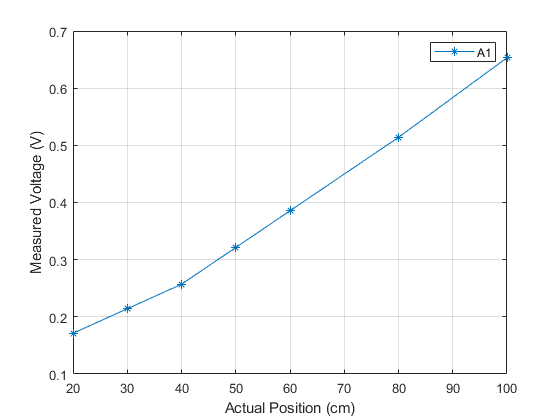

%Plot and store commanded position data vs. actual position
plot(positionData(:,1),rawSharpData(:,1), '-*')
xlabel('Actual Position (cm)');
ylabel('Measured Voltage (V)');
legend('A1');
grid


% save bluePosition.dat positionData -ascii

**Clean Shutdown**

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = robotPi`

## `h.execute('sudo shutdown -h now')`